# 1125_上机实验

**1. **

使用matlab命令去对比字符串A = ‘I am good’ 和字符串 B = ‘I am fine’

a)彼此不相同

b)哪些字符不同。

A = 'I am good';
B = 'I am fine';
disp('两个字符串相同的字符有：');

两个字符串相同的字符有：


A == B

ans = 1×9 logical 数组
   1   1   1   1   1   0   0   0   0


disp('两个字符串不相同的字符有：');

两个字符串不相同的字符有：


A ~= B

ans = 1×9 logical 数组
   0   0   0   0   0   1   1   1   1


**2. **编写一段程序逆转给定的字符串。例如，逆转s1 = ‘I like the letter E’变成s2= ‘E rettel eht ekil I’。

s1 = 'I like the letter E';
s2 = s1(end:-1:1);
disp('原字符串为:')

原字符串为:


disp(s1);

I like the letter E


disp('逆序后的字符串为:');

逆序后的字符串为:


disp(s2);

E rettel eht ekil I


**3.** 已知有字符串“Artificial123Intelligence”

    a) 取出第4到第10个字符组成新字符串，并输出；

    b) 把上述字符串中偶数位置字符取出，组成新字符串；

    c) 去掉字符串中的数字，并输出;

    d) 将字符串中的大写字符转换为小写，输出新字符串

disp('第3题:')

第3题:


str = 'Artificial123Intelligence'

str = 'Artificial123Intelligence'

disp('第4到第10个字符组成新字符串:')

第4到第10个字符组成新字符串:


disp(str(4:10));

ificial


disp('把上述字符串中偶数位置字符取出，组成新字符串:');

把上述字符串中偶数位置字符取出，组成新字符串:


disp(str(2:2:end));

riiil2Itliec


disp('去掉字符串中的数字，并输出')

去掉字符串中的数字，并输出


k = length(str);
b='';
for i=1:k
    c=str(i);
    f = str2num(c);
    if isempty(f)
        b=strcat(b,c);
    end
end
disp(b);

ArtfcalIntellgence


disp('将字符串中的大写字符转换为小写，输出新字符串:')

将字符串中的大写字符转换为小写，输出新字符串:


disp(lower(str));

artificial123intelligence


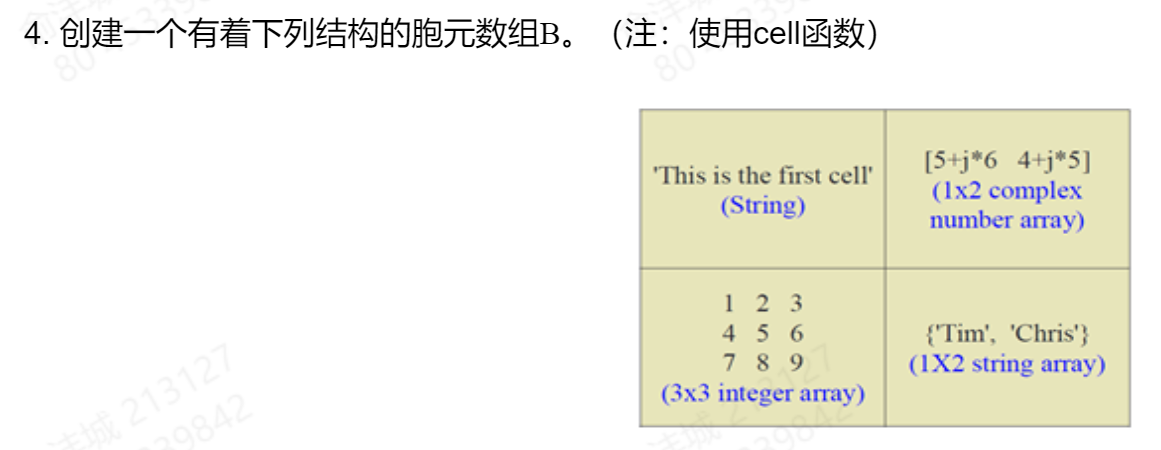

a = complex(5,6);
b = complex(4,5);
x = ['This is the first cell', ...
    [a,b], ...
    [1,2,3;4,5,6;7,8,9], ...
    {'Tim','Chris'}];
x = cell(x);
disp(x)

  列 1

    {'This is the fir…'}

  列 2 至 3

    {1×2 double}    {3×3 double}

  列 4 至 5

    {'Tim'}    {'Chris'}



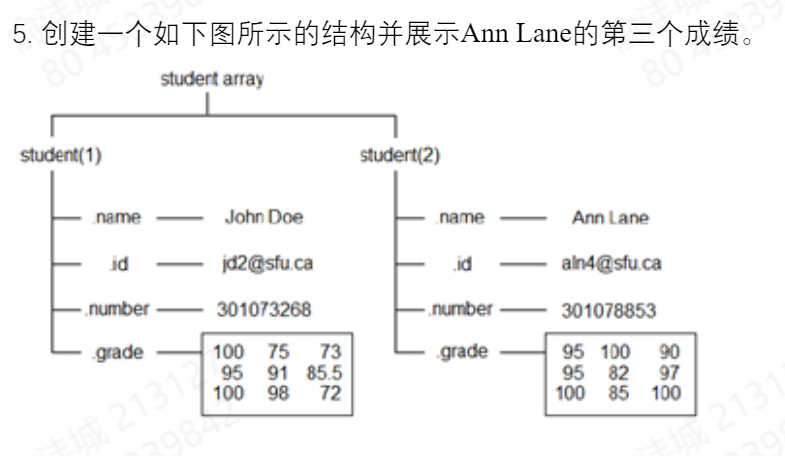

student(1).name = 'John Doe';
student(1).id = 'jd2@sfu.ca';
student(1).number = 301073268;
student(1).grade = [100,7,73;95,91,85.5;100,98,72];

student(2).name = 'Ann Lane';
student(2).id = 'aln4@sfu.ca';
student(2).number = 301078853;
student(2).grade = [95,100,90;95,82,97;100,85,100];

disp('Ann Lane的第三个成绩为:');

Ann Lane的第三个成绩为:


disp(student(2).grade(3));

   100



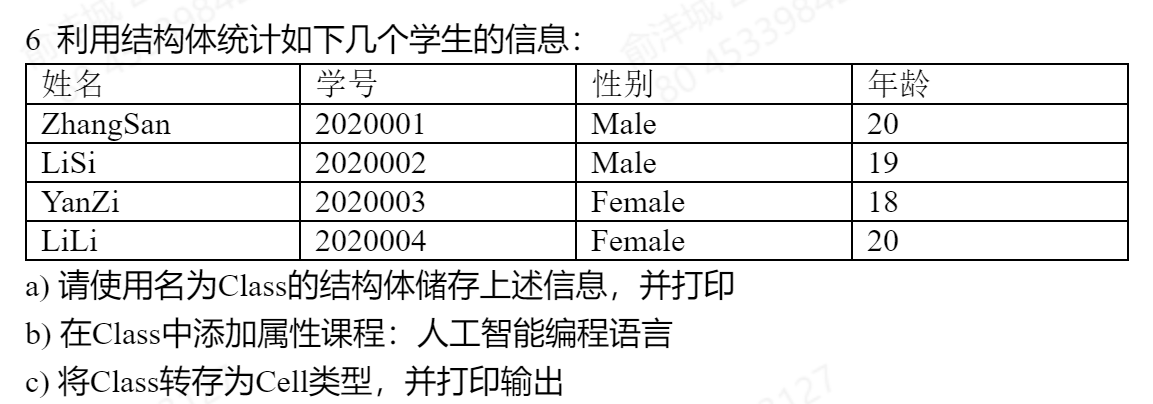

% 1
class = struct('name',{'ZhangSan','LiSi','YanZi','LiLi'}, ...
    'id',{'2020001','2020002','2020003','2020004'}, ...
    'sex',{'Male','Male','Female','Female'}, ...
    'age',{20,19,28,20});
class

class = 包含以下字段的 1×4 struct 数组:
    name
    id
    sex
    age


% 2
% course = struct('course','人工智能编程语言');
for i = 1:4
    class(i).courseName = "人工智能编程语言";
end
disp(class);

  包含以下字段的 1×4 struct 数组:

    name
    id
    sex
    age
    courseName



% 3
class = struct2cell(class);
disp(class)


(:,:,1) = 

    {'ZhangSan'       }
    {'2020001'        }
    {'Male'           }
    {[             20]}
    {["人工智能编程语言"]}


(:,:,2) = 

    {'LiSi'           }
    {'2020002'        }
    {'Male'           }
    {[             19]}
    {["人工智能编程语言"]}


(:,:,3) = 

    {'YanZi'          }
    {'2020003'        }
    {'Female'         }
    {[             28]}
    {["人工智能编程语言"]}


(:,:,4) = 

    {'LiLi'           }
    {'2020004'        }
    {'Female'         }
    {[             20]}
    {["人工智能编程语言"]}

